## PoC - Inferencia verificable con MATLAB

Álvaro Martínez Alfaro

Criptografía, Escuela Superior de Ingeniería Informática, UCLM

Albacete, España

**Nota:** Esta PoC implementa la verificabilidad algebraica (R1CS, QAP, Schwartz-Zippel) que constituye el núcleo de un SNARK, pero no la propiedad de conocimiento cero que lo haría un zk-SNARK. Los PCS, el mecanismo de blinding y Fiat-Shamir se desarrollan en la memoria, pero su implementación queda fuera del alcance de este desarrollo.

### 1 - Introducción

Este fichero implementa, paso a paso, una prueba de concepto del proceso completo de inferencia verificable en una red neuronal. El objetivo no es construir un sistema criptográfico o *framework* completo, sino ilustrar cada etapa del proceso.

El punto de partida es el siguiente problema: un proveedor ejecuta una red neuronal sobre unos datos y entrega un resultado. ¿Cómo puede el usuario verificar que el cálculo se realizó correctamente sin que el proveedor revele los pesos? Como se desarrolla en la Sección 2.3 de la memoria, la solución pasa por traducir todo el proceso de inferencia a un sistema de restricciones aritméticas que un verificador puede comprobar, sin que el proveedor revele sus secretos.

Para mantener la implementación manejable, se trabaja con una red neuronal pequeña que contiene dos neuronas de entradas, dos neuronas ocultas con función de activación *ReLU* y una salida, trabajando bajo un cuerpo "modesto" (${\mathbb{F}}_{65537}$). Las ideas, sin embargo, son similares a las aplicadas por los *frameworks* modernos revisados en la Sección 2.3.4 a redes de millones de parámetros.

El recorrido tiene cinco etapas: **cuantización** de los pesos a aritmética entera, **inferencia** en el cuerpo finito, construcción del **sistema R1CS**, transformación al **programa aritmético cuadrático **(QAP) y, finalmente, **generación y verificación** de la prueba apoyándonos en el lema de *Schwartz-Zippel*.

### 1.1 - Definición de parámetros

Como se ha visto en la memoria, los protocolos critográficos de conocimiento cero no operan con números reales, sino con enteros dentro de un **cuerpo** (${\mathbb{F}}_p$): un conjunto cerrado de valores $\left\lbrace 0,1,\ldots,p-1\right\rbrace$ en el que la suma, la resta y la multiplicación están definidas módulo $p$. Así, es necesario fijar dos parámetros que determinan ese espacio aritmético.

En primer lugar, $p=65537$ es el primo que define el cuerpo. Se trata de un primo de *Fermat* ($2^{16} +1$) y desde el punto de vista práctico, es lo suficientemente grande como para albergar todos los valores que aparecerán durante la inferencia y, también, lo suficientemente pequeño como para que cualquier producto de dos elementos del cuerpo quepa exactamente en un *double* de MATLAB sin pérdida de precisión.

p = 65537;

Luego, definimos el factor de escala que permite traducir los pesos en punto flotante a enteros; en este caso, el factor de escala es 16, ya que con los pesos y entradas de este ejemplo, los productos intermedios nunca superan *p*, evitando así la necesidad de reescalar entre capas. Con él, un peso como $0\ldotp 5$ se convierte en 8 ($=0\ldotp 5\times 16$); uno como $-0\ldotp 5$ se convierte en $-8$, que dentro del cuerpo se representa como $p-8=65529$.

fescala = 16;

### 1.2 - Definición de la red neuronal

La red neuronal que se va a verificar tiene una arquitectura deliberadamente simple: dos neuronas de entrada, dos neuronas ocultas con función de activación *ReLU* y una neurona de salida lineal, sin términos de sesgo. Es suficiente para ilustrar todas las etapas del proceso sin añadir complejidad innecesaria.

Los pesos escogidos son múltiplos exactos de $\frac{1}{16}$, es decir, del inverso del factor de escala. Esto garantiza que la cuantización no introduce ningún error de redondeo, simplificando así la verificación de los resultados en las secciones siguientes. Además, la entrada $x=\left\lbrack 0\ldotp 5;1\ldotp 0\right\rbrack$ tiene una propiedad interesante; combinada con los pesos de la primera capa, provoca que una de las dos neuronas ocultas reciba una pre-activación negativa. *ReLU *la anulará y ese comportamiento no trivial será visible a lo largo de todo el proceso.

La siguiente celda de código define la arquitectura, aunque se puede observar una representación más visual en la imagen siguiente.

W1 = [0.5, -0.5; 0.375, 0.125]; % capa oculta (2x2)
W2 = [0.5, 0.25]; % capa de salida (1x2)
x  = [0.5; 1.0]; % vector de entrada

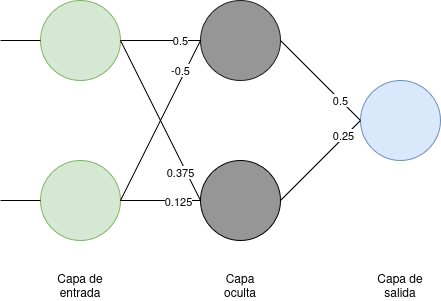

*Arquitectura de la red neuronal utilizada*

### 2 - Cuantización de la red neuronal

Como se ha comentado, los protocolos criptográficos solo entienden de enteros positivos dentro del cuerpo finito. Antes de poder verificar nada, es necesario traducir todos los valores de la red (*pesos *y *entradas*) a ese dominio. Este proceso es la **cuantización**.

La operación es directa: multiplicar cada valor por *fescala* y redondear al entero más cercano. Un peso de $0\ldotp 5$ se convierte en $8$; una entrada de $1\ldotp 0$ se convierte en $16$. 

Comenzamos definiendo una función anónima que realice esta conversión; la denominaremos *cuant*. Esta aplica el módulo $p$ al producto entre el valor recibido como parámetro y el factor de escala.

cuant = @(v) mod(round(v * fescala), p);

Con ella, cuantizamos, en primer lugar, la entrada

x1_c  = cuant(x(1)); x2_c  = cuant(x(2));
fprintf("Entrada cuantizada en F_%d: [%.2f, %.2f] -> [%d, %d].", p, x(1), x(2), x1_c, x2_c)

Entrada cuantizada en F_65537: [0.50, 1.00] -> [8, 16].

en segundo lugar, los pesos de la capa oculta

w11_c = cuant(W1(1,1)); w12_q = cuant(W1(1,2));
w21_c = cuant(W1(2,1)); w22_q = cuant(W1(2,2));
fprintf("Capa oculta cuantizada en F_%d: [%.2f, %.2f; %.2f, %.2f] -> [%d, %d; %d, %d].", p, W1(1,1), W1(1,2), W1(2,1), W1(2,2), w11_c, w12_q, w21_c, w22_q)

Capa oculta cuantizada en F_65537: [0.50, -0.50; 0.38, 0.12] -> [8, 65529; 6, 2].

y, finalmente, los pesos de la capa de salida

w31_c = cuant(W2(1)); w32_c = cuant(W2(2));
fprintf("Capa oculta cuantizada en F_%d: [%.2f, %.2f] -> [%d, %d].", p, W2(1), W2(2), w31_c, w32_c)

Capa oculta cuantizada en F_65537: [0.50, 0.25] -> [8, 4].

Es interesante destacar el caso del peso negativo $-0\ldotp 5$ en la capa oculta. Como se ha comentado, en ${\mathbb{F}}_p$ no existen los negativos, pero sí existe el **inverso aditivo**: el valor que sumado a $8$ da $0$ dentro del cuerpo. Ese valor es $p-8=65529$. A efectos aritméticos, operar con $65529\;\mathrm{mod}\;p$ es equivalente a operar con $-8$, y el resultado de cualquier cálculo que lo involucre será correcto siempre que se aplique el módulo. 

### 3 - Inferencia

#### 3.1 - Inferencia real

En primer lugar, realizamos una inferencia en punto flotante, como se realizaría con la red neuronal real, que servirá como referencia. Se ejecuta en primer lugar para disponer de los valores esperados con los que comparar el resultado cuantizado. El dato más relevante de la salida es que la pre-activación de la primera neurona oculta vale $-0\ldotp 25$, que es el valor negativo que *ReLU* anulará.

Comenzamos definiendo la función *ReLU *mediante una función anónima.

relu = @(v) max(0, v);

Aplicamos el producto matricial entre la entrada y los pesos de la capa oculta

s1_float = W1 * x

s1_float =    -0.2500
    0.3125


y, tras ello, la función de activación

a1_float = relu(s1_float)

a1_float =          0
    0.3125


Al resultado de la función de activación en cada neurona de la capa oculta se le aplican los pesos de la capa de salida, de nuevo, mediante el producto matricial

y_float = W2 * a1_float;
vpa(y_float, 10)

$$ans = 0.078125$$

y vemos que el resultado es $0\ldotp 078125$; esta es la salida de la red neuronal para la entrada dada.

#### 3.2 - Inferencia cuantizada

Ahora, se repite el proceso de inferencia pero dentro del cuerpo finito. Cada multiplicación y cada suma se realiza módulo $p$ y los valores negativos se representan como sus inversos aditivos.

Primero, cada conexión entre la capa de entrada y la capa oculta implica una multiplicación. Dentro del cuerpo finito, multiplicar dos enteros y aplicar módulo $p$ garantiza que el resultado permanece en el rango válido. Es interesante destacar que $\mathrm{t2}$ resulta en un valor próximo a $p$; es el producto que involucra el peso negativo y su resultado, $65529$, representa el número negativo expresado como inverso aditivo.

t1 = mod(w11_c * x1_c, p) % w11 * x1

t1 = 64

t2 = mod(w12_q * x2_c, p) % w12 * x2  (negativo en F_p)

t2 = 65409

t3 = mod(w21_c * x1_c, p) % w21 * x1

t3 = 48

t4 = mod(w22_q * x2_c, p) % w22 * x2

t4 = 32

Ahora, la pre-activación de cada neurona oculta es la suma de sus productos de entrada, aplicando también módulo $p$. $65473$ es el resultado de sumar $64$ y $65409$, dos valores que en el cuerpo finito se combinan para dar $p-64$, es decir, el equivalente a $-64$.

s1_1_q = mod(t1 + t2, p) % pre-activacion neurona 1

s1_1_q = 65473

s1_2_q = mod(t3 + t4, p) % pre-activacion neurona 2

s1_2_q = 80

Tras ello, en el cuerpo finito no existe el concepto de número negativo como tal, pero sí una convención. Como se indica en la memoria, los valores en $\left\lbrack 0,\frac{p}{2}\right)$ se interpretan como positivos y los valores en $\left(\frac{p}{2},p-1\right\rbrack$ como negativos. Comprobar si una pre-activación es positiva o negativa es, simplemente, comparar con $\frac{p}{2}$. Así, $\mathrm{sgnX}$, tal como se define en la siguiente celda, será $1$ si la pre-activación es menor que $\frac{p}{2}$ y $0$ en caso de que sea negativa.

sgn1 = double(s1_1_q < p/2) % 65473 -> negativo (-64)

sgn1 = 0

sgn2 = double(s1_2_q < p/2) % 80 -> positivo

sgn2 = 1

Con ello, aplicamos nuestra función *ReLU* sobre cuerpos finitos; esto es, la multiplicación por el *bit* de signo $a=s\cdot \mathrm{sgn}\;\left(\mathrm{mod}\;p\right)$. Cuando la pre-activación es negativa, la función *ReLU* se anula y, cuando es positiva, mantiene el propio valor.

a1_1_q = mod(s1_1_q * sgn1, p)

a1_1_q = 0

a1_2_q = mod(s1_2_q * sgn2, p)

a1_2_q = 80

Finalmente, la capa de salida repite el mismo patrón de productos modulares y suma

t5 = mod(w31_c * a1_1_q, p)

t5 = 0

t6 = mod(w32_c * a1_2_q, p)

t6 = 320

y_q = mod(t5 + t6, p)

y_q = 320

y el resultado, como se puede observar, es $320$. Ahora bien, ¿qué hacemos con él? Este está expresado en unidades ${\mathrm{SCALE}}^3$, ${16}^3 =4096$, pues los productos se han acumulado a lo largo de dos capas sin reescalar. Dividiendo por $4096$ recuperamos $0\ldotp 078125$ que, recordemos, es el resultado de la inferencia real.

y_decuant = y_q / fescala^3;
fprintf("Resultado inferencia real: %g\nResultado inferencia cuantizada: %d (decuantizado: %g)", y_float, y_q, y_decuant)

Resultado inferencia real: 0.078125
Resultado inferencia cuantizada: 320 (decuantizado: 0.078125)

De esta forma, ya tenemos nuestra red neuronal cuantizada y hemos verificado que la inferencia es correcta, pero esto por sí solo no demuestra nada ante un verificador externo. El siguiente paso es traducir toda la secuencia de operaciones a un lenguaje que el verificador pueda comprobar de forma rigurosa.

### 4 - Construcción del sistema R1CS

Verificar que una inferencia se ha realizado correctamente requiere expresarla de una forma que un protocolo criptográfico pueda entender. Los protocolos de conocimiento cero no comprenden nada acerca de neuronas o capas. El **sistema R1CS** (*Rank-1 Constraint System*) es esa traducción, una lista de restricciones de la forma (informal) $\mathrm{algo}\times \mathrm{algo}=\mathrm{algo}$, donde cada *algo* es una combinación lineal de las variables del sistema. Si todas las restricciones se satisfacen simultáneamente, el cálculo se considera correcto.

Cada multiplicación de la inferencia (producto de un peso por una activación, cada aplicación de *ReLU*) debe convertirse en una restricción independiente. Las sumas, sin embargo, pueden absorberse dentro de las combinaciones lineales sin generar nuevas restricciones.

Para que el sistema funcione, todas las variables que aparecen en las restricciones (entradas, pesos, valores intermedios y salida) deben recogerse en un único vector, llamado **testigo**. Este es el objeto que la parte probadora conoce (el proveedor del modelo) y que la parte verificadora (el usuario del modelo) quiere comprobar sin verlo.

Vamos a definir el testigo. Este recoge todas las variables que intervienen en la inferencia, organizadas en un orden fijo. La primera posición es siempre la constante 1, que permite expresar términos independientes dentro de las combinaciones lineales. A continuación, aparecen las entradas y la salida, que son valores *públicos*, tanto la parte probadora como la verificadora los conocen. El resto, son valores *privados*, como los pesos de la red, los productos intermedios de cada capa, los *bits* de signo y las activaciones tras *ReLU*. La siguiente tabla proporciona una representación gráfica del vector testigo, que se define en la celda de código posterior.

z = [1; x1_c; x2_c; y_q; ...
     w11_c; w12_q; w21_c; w22_q; w31_c; w32_c; ...
     t1; t2; t3; t4; ...
     sgn1; a1_1_q; sgn2; a1_2_q; ...
     t5; t6];
fprintf("Vector testigo: z = ["); fprintf("%d ", z); fprintf("]");

Vector testigo: z = [1 8 16 320 8 65529 6 2 8 4 64 65409 48 32 0 0 1 80 0 320 ]

Con el vector testigo definido, el sistema R1CS se representa mediante tres matrices, $A,B,C$, de dimensiones $m\times n$, donde $m$ es el número de restricciones y $n$ es la longitud del vector testigo. En nuestro caso, las restricciones son los productos peso-entrada, las aplicaciones de *ReLU*, los signos de la función *ReLU*, los productos peso-activación y la suma de salida. La siguiente tabla muestra tales restricciones.

Cada fila de las matrices corresponde a una restricción, y cada columna corresponde a una variable del testigo. La idea es que, para cada restricción $i$, los productos escalares de la fila $i$ de $A$, $B$ y $C$ con el testigo $z$ seleccionan los operandos de esa multiplicación

- $A\cdot z$ extrae el operando izquierdo de cada restricción

- $B\cdot z$ extrae el operando derecho

- $C\cdot z$ extrae el resultado esperado

La verificación consiste en comprobar que, para cada fila, el producto de los dos primeros es igual al tercero, todo ello módulo $p$. Si se cumple para las $11$ filas, la inferencia es correcta.

La mayor parte de las entradas de estas matrices son cero, pues cada restricción solo involucra unas pocas variables del testigo. Por eso, $A,B,C$ son matrices dispersas y, al construirlas, solo es necesario indicar las entradas no nulas. Así, la construcción es directa; comenzamos definiendo los valores de $m$ y $n$ e inicializando las matrices con ceros.

n = 20; % numero de variables en z
m = 11; % numero de restricciones
A = zeros(m, n); B = zeros(m, n); C = zeros(m, n);

Para una restricción del tipo $w\cdot x=t$, la fila correspondiente de $A$ tiene un $1$ en la columna de $w$, la de $B$ un 1 en la columna de $x$ y la de $C$ un $1$ en la columna de $t$. Las restricciones $5$ y $7$, sin embargo, son un caso especial. La pre-activación de cada neurona es la suma de dos productos, por lo que la fila de $A$ tiene dos unos, uno en la columna de $t$ y otro en la de $t_2$. Eso es todo lo necesario para expresar una suma dentro de R1CS.

Definimos así los valores necesarios en las matrices.

A(1,5)=1;               B(1,2)=1;           C(1,11)=1; % 1: w11*x1=t1
A(2,6)=1;               B(2,3)=1;           C(2,12)=1; % 2: w12*x2=t2
A(3,7)=1;               B(3,2)=1;           C(3,13)=1; % 3: w21*x1=t3
A(4,8)=1;               B(4,3)=1;           C(4,14)=1; % 4: w22*x2=t4
A(5,11)=1;A(5,12)=1;    B(5,15)=1;          C(5,16)=1; % 5: (t1+t2)*sgn1=a1_1
A(6,15)=1;              B(6,15)=1;          C(6,15)=1; % 6: sgn1^2=sgn1
A(7,13)=1;A(7,14)=1;    B(7,17)=1;          C(7,18)=1; % 7: (t3+t4)*sgn2=a1_2
A(8,17)=1;              B(8,17)=1;          C(8,17)=1; % 8: sgn2^2=sgn2
A(9,9)=1;               B(9,16)=1;          C(9,19)=1; % 9: w31*a1_1=t5
A(10,10)=1;             B(10,18)=1;         C(10,20)=1; % 10: w32*a1_2=t6
A(11,19)=1;A(11,20)=1;  B(11,1)=1;          C(11,4)=1;  % 11: (t5+t6)*1=y_q

Con las matrices construidas, la verificación del sistema R1CS es inmediata: se calculan los tres productos matriciales con el testigo, se multiplican elemento a elemento los dos primeros (producto de *Hadamard*) y se comprueba que el resultado coincide con el tercero, todo módulo $p$.

Tras ejecutar la siguiente celda se observa el resultado para cada restricción. La restricción 5, en concreto, muestra cómo el operando izquierdo vale $65473$ (pre-activación negativa), el derecho vale $0$ (por ser negativa) y el resultado es $0$, ilustrando cómo se ha conseguido transformar la operación *ReLU* a cuerpo finito.

Az = mod(A * z, p);
Bz = mod(B * z, p);
Cz = mod(C * z, p);
izq_r1cs = mod(Az .* Bz, p); % producto de Hadamard
% verificación de cada restricción
for i = 1:m
    verif = (izq_r1cs(i) == Cz(i));
    marca = 'OK';  
    if ~verif
        marca = 'ERROR';
    end
    fprintf('[%s] Restricción %2d: %6d x %6d = %6d  (esperado %6d)\n', marca, i, Az(i), Bz(i), izq_r1cs(i), Cz(i));
end

[OK] Restricción  1:      8 x      8 =     64  (esperado     64)
[OK] Restricción  2:  65529 x     16 =  65409  (esperado  65409)
[OK] Restricción  3:      6 x      8 =     48  (esperado     48)
[OK] Restricción  4:      2 x     16 =     32  (esperado     32)
[OK] Restricción  5:  65473 x      0 =      0  (esperado      0)
[OK] Restricción  6:      0 x      0 =      0  (esperado      0)
[OK] Restricción  7:     80 x      1 =     80  (esperado     80)
[OK] Restricción  8:      1 x      1 =      1  (esperado      1)
[OK] Restricción  9:      8 x      0 =      0  (esperado      0)
[OK] Restricción 10:      4 x     80 =    320  (esperado    320)
[OK] Restricción 11:    320 x      1 =    320  (esperado    320)


### 5 - Transformación a *Programa Aritmético Cuadrático *(QAP)

Ya tenemos nuestro sistema R1CS satisfecho, lo cual es condición necesaria, pero no suficiente para construir una prueba verificable de forma eficiente. El problema que surge ahora es que la parte verificadora, para verificar la inferencia mediante las restricciones, tendría que tener acceso al testigo; se rompe la condición de conocimiento cero.

La solución es condensar todas las restricciones en un único objeto matemático que pueda verificar sin revelar nada; un **polinomio**. Esa transformación es el **Programa Aritmético Cuadrático**, o QAP. La idea central es la siguiente: si se asigna un número entero a cada restricción $\left(1,2,\ldots,11\right)$ y se interpolan polinomios que pasen por los valores de las matrices $A,B,C$ en esos puntos, se obtienen tres polinomios $A\left(x\right),B\left(x\right),C\left(x\right)$ que codifican todo el sistema de restricciones. La propiedad clave es que el polinomio $T\left(x\right)=A\left(x\right)\cdot B\left(x\right)-C\left(x\right)$ se anula exactamente en los puntos $1,2,\ldots,11$ y solo si el testigo satisface todas las restricciones. En otras palabras, si el testigo es válido, $T\left(x\right)$ se anula en los $m$ puntos de evaluación, por lo que es divisible. Recíprocamente, comprobar esa divisibilidad equivale a verificar que las $m$ restricciones se cumplen simultáneamente, condensando todo el sistema en una única identidad polinómica.

Lo importante es que verificar una divisibilidad polinómica en un único punto aleatorio es más eficiente que comprobar 11 restricciones individuales y, más importante, puede hacerse sin revelar el testigo.

El proceso tiene tres pasos: construir los polinomios $A\left(x\right),B\left(x\right),C\left(x\right)$ mediante interpolación de *Lagrange*, calcular $T\left(x\right)$ y dividirlo por $Z\left(x\right)$ para obtener el cociente $H\left(x\right)$ y verificar la identidad en un punto aleatorio.

La interpolación de *Lagrange* permite construir, dado un conjunto de puntos, el único polinomio de grado mínimo que pasa por todos ellos. Aquí se aplica columna a columna sobre las matrices $A,B,C$: para cada variable del testigo, se toman los valores que esa variable aporta a cada restricción (es decir, los valores de su columna en $A,B$ o $C$ evaluados en los puntos $1,2,\ldots,11$) y se interpola el polinomio correspondiente.

El polinomio $A\left(x\right)$ se construye entonces como la suma de todos esos polinomios, cada uno escalado por el valor correspondiente del testigo. El resultado es un polinomio de grado 10 que, evaluado en cualquier punto entero $1\le i\le 11$, devuelve el valor del operando izquierdo de la restricción $i$. Lo mismo ocurre con $B\left(x\right)$ y $C\left(x\right)$.

Al ejecutar la siguiente celda, se construyen los polinomios y se comprueba que la interpolación es correcta, es decir, $A\left(i\right),B\left(i\right),C\left(i\right)$ reproducen exactamente los valores de las matrices en cada punto de evaluación.

t_pts = 1:m; % puntos de evaluacion: {1, 2, ..., 11}

A_poli = zeros(1, m);
B_poli = zeros(1, m);
C_poli = zeros(1, m);

for j = 1:n
    if z(j) == 0 % contribucion nula: z[j]*L = 0
        continue; 
    end

    col_A = A(:, j)';
    col_B = B(:, j)';
    col_C = C(:, j)';

    % si cualquiera de los puntos de la columna actual es distinto de 0
    % aplicamos interpolación de Lagrange (función auxiliar)
    if any(col_A ~= 0)
        Lj = lagrange_interp_fp(t_pts, col_A, p);
        A_poli = poly_add_fp(A_poli, scalar_mul_poly(z(j), Lj, p), p);
    end
    if any(col_B ~= 0)
        Lj = lagrange_interp_fp(t_pts, col_B, p);
        B_poli = poly_add_fp(B_poli, scalar_mul_poly(z(j), Lj, p), p);
    end
    if any(col_C ~= 0)
        Lj = lagrange_interp_fp(t_pts, col_C, p);
        C_poli = poly_add_fp(C_poli, scalar_mul_poly(z(j), Lj, p), p);
    end
end

% Verificación
for i = 1:m
    Ai = poly_eval_fp(A_poli, i, p);
    Bi = poly_eval_fp(B_poli, i, p);
    Ci = poly_eval_fp(C_poli, i, p);
    verif = (Ai == Az(i)) && (Bi == Bz(i)) && (Ci == Cz(i));
    marca = 'OK';  
    if ~verif
        marca = 'ERROR';
    end
    fprintf('[%s] Punto %2d:  A=%6d (R1CS=%6d)  B=%6d (R1CS=%6d)  C=%6d (R1CS=%6d)\n', marca, i, Ai, Az(i), Bi, Bz(i), Ci, Cz(i));
end

[OK] Punto  1:  A=     8 (R1CS=     8)  B=     8 (R1CS=     8)  C=    64 (R1CS=    64)
[OK] Punto  2:  A= 65529 (R1CS= 65529)  B=    16 (R1CS=    16)  C= 65409 (R1CS= 65409)
[OK] Punto  3:  A=     6 (R1CS=     6)  B=     8 (R1CS=     8)  C=    48 (R1CS=    48)
[OK] Punto  4:  A=     2 (R1CS=     2)  B=    16 (R1CS=    16)  C=    32 (R1CS=    32)
[OK] Punto  5:  A= 65473 (R1CS= 65473)  B=     0 (R1CS=     0)  C=     0 (R1CS=     0)
[OK] Punto  6:  A=     0 (R1CS=     0)  B=     0 (R1CS=     0)  C=     0 (R1CS=     0)
[OK] Punto  7:  A=    80 (R1CS=    80)  B=     1 (R1CS=     1)  C=    80 (R1CS=    80)
[OK] Punto  8:  A=     1 (R1CS=     1)  B=     1 (R1CS=     1)  C=     1 (R1CS=     1)
[OK] Punto  9:  A=     8 (R1CS=     8)  B=     0 (R1CS=     0)  C=     0 (R1CS=     0)
[OK] Punto 10:  A=     4 (R1CS=     4)  B=    80 (R1CS=    80)  C=   320 (R1CS=   320)
[OK] Punto 11:  A=   320 (R1CS=   320)  B=     1 (R1CS=     1)  C=   320 (R1CS=   320)


fprintf('Grado de A(x): %d B(x): %d C(x): %d', length(A_poli)-1, length(B_poli)-1, length(C_poli)-1);

Grado de A(x): 10 B(x): 10 C(x): 10

El polinomio de anulación $Z\left(x\right)=\left(x-1\right)\left(x-2\right)\cdots \left(x-11\right)$ es el denominador común de todo el sistema. Se anula exactamente en los 11 puntos de evaluación y ninguno más. Su papel es actuar como referencia, de forma que si $T\left(x\right)=A\left(x\right)\cdot B\left(x\right)-C\left(x\right)$ es divisible por $Z\left(x\right)$, significa que $T\left(x\right)$ también se anula en esos 11 puntos, lo que implica que todas las restricciones se satisfacen. Este polinomio, además, es de grado 11, uno más que $A,B$ y $C$.

Z_poli = [1];
for i = 1:m
    Z_poli = poly_mul_fp(Z_poli, [1, mod(-i, p)], p);
end
fprintf('Grado de Z(x): %d (igual al número de restricciones)\n\n', length(Z_poli)-1);

Grado de Z(x): 11 (igual al número de restricciones)



Con los tres polinomios construidos, el siguiente paso es calcular $T\left(x\right)=A\left(x\right)\cdot B\left(x\right)-C\left(x\right)$, polinomio que resume todo el sistema de restricciones en un único objeto

AB_poli = poly_mul_fp(A_poli, B_poli, p); % A(x)*B(x) mod p
neg_C   = scalar_mul_poly(p - 1, C_poli, p); % -C(x) mod p
T_poli  = poly_add_fp(AB_poli, neg_C, p); % A(x)*B(x)-C(x) mod p

fprintf('Grado de A(x)*B(x): %d T(x): %d\n', length(AB_poli)-1, length(T_poli)-1);

Grado de A(x)*B(x): 20 T(x): 20


Ahora, para obtener el cociente $H\left(x\right)=\frac{T\left(x\right)}{Z\left(x\right)}$ se realiza una división polinómica entera sobre el cuerpo finito. Si el resto es cero, la prueba es válida, es decir, existe un polinomio $H\left(x\right)$ de grado menor que el de $T\left(x\right)$ que satisface la identidad $T\left(x\right)=H\left(x\right)\cdot Z\left(x\right)$. Si el resto no fuese cero, significaría que alguna restricción no se cumple y el testigo es inconsistente (ha sido alterado).

[H_poli, rem_poli] = poly_div_fp(T_poli, Z_poli, p);

Ejecutando la siguiente celda se puede comprobar que el resto es efectivamente cero y que el grado de $H\left(x\right)$ es 9, el máximo esperado para una división de un polinomio de grado 20 entre uno de grado 11.

rem_is_zero = isempty(rem_poli) || all(rem_poli == 0);
if rem_is_zero
    fprintf('[OK] T(x) es exactamente divisible por Z(x).');
    fprintf('     Grado de H(x) = %d (maximo esperado: %d)', length(H_poli)-1, length(T_poli)-1 - (length(Z_poli)-1));
else
    fprintf('[ERROR] T(x) no es divisible por Z(x). Resto: ');
    fprintf('%d ', rem_poli);
end

[OK] T(x) es exactamente divisible por Z(x).

     Grado de H(x) = 9 (maximo esperado: 9)

Llegados a este punto se dispone de todo lo necesario para la verificación, esto es, los polinomios $A\left(x\right),B\left(x\right),C\left(x\right)$, el cociente $H\left(x\right)$ y el polinomio de anulación $Z\left(x\right)$, que la probadora haría públicos o enviaría a una entidad de verificación.

### 6 - Verificación

Comprobar que $T\left(x\right)=H\left(x\right)\cdot Z\left(x\right)$ como polinomios completos requeriría que la verificadora conociera todos los coeficientes y, por tanto, conocer el testigo. La solución la obtenemos por el **lema de Schwartz-Zippel**: sean $p_1 ,p_2$ dos polinomios distintos de grado $\le d$ sobre ${\mathbb{F}}_p$. La probabilidad de que coincidan en un punto $r$ elegido uniformemente al azar está acotada por $\frac{d}{p}$. Con $p=65537$ y grado $20$,

vpa(20/65537, 5)

$$ans = 0.00030517$$

vemos que la probabilidad es aproximadamente $0\ldotp 03%$.

Con ello, el protocolo es simple. La verificadora escoge un punto aleatorio $r$ y comprueba que $A\left(r\right)\cdot B\left(r\right)-C\left(r\right)=H\left(r\right)\cdot Z\left(r\right)\;\left(\mathrm{mod}\;p\right)$. Si se cumple, la prueba es válida con alta probabilidad. La probadora no necesita revelar ningún coeficiente, solo evaluar los polinomios en ese punto.

Comenzamos generando el punto $r$. En un sistema real, este se generaría de forma no interactiva mediante la heurística de *Fiat-Shamir*, que usa funciones *hash* criptográficas para producir un desafío pseudoaleatorio que ninguna de las partes puede predecir ni manipular. Aquí, seleccionaremos un entero aleatorio $12\le r\le 23061912$, evitando el rango $\left\lbrack 1,11\right\rbrack$ por el hecho de que en esos puntos $T\left(x\right)$ se anula por construcción, por lo que la comprobación sería ciera para cualquier $H$, aunque sea incorrecto.

r = randi([12, p-1]);
fprintf('Punto de evaluacion: r = %d', r);

Punto de evaluacion: r = 6403

A continuación, evaluamos todos los polinomios en el punto $r$

A_r = poly_eval_fp(A_poli, r, p);
B_r = poly_eval_fp(B_poli, r, p);
C_r = poly_eval_fp(C_poli, r, p);
H_r = poly_eval_fp(H_poli, r, p);
Z_r = poly_eval_fp(Z_poli, r, p);

cuyo resultado muestran las siguientes dos celdas

fprintf('A(r) = %d, B(r) = %d, C(r) = %d', A_r, B_r, C_r);

A(r) = 53301, B(r) = 59963, C(r) = 18417

fprintf('H(r) = %d, Z(r) = %d', H_r, Z_r);

H(r) = 34948, Z(r) = 30112

Con ello, la verificación se reduce a comprobar una única igualdad. Calculamos ambos miembros

res_izq = mod(mod(A_r * B_r, p) - C_r + p, p);
res_der = mod(H_r * Z_r, p);

cuyo resultados se muestran en las siguientes dos celdas

fprintf('LHS = A(r)*B(r) - C(r) mod p = %d\n', res_izq);

LHS = A(r)*B(r) - C(r) mod p = 26567


fprintf('RHS = H(r)*Z(r) mod p = %d\n', res_der);

RHS = H(r)*Z(r) mod p = 26567


Como se puede observar, ambos coinciden, por lo que la verificación ha sido exitosa. El cálculo completo de la red neuronal ha quedado certificado por una única igualdad aritmética evaluada en un punto aleatorio.

Para finalizar, podemos comprobar qué ocurre si el testigo es alterado por la probadora. Vamos a "simular" que la probadora ha modificado su red neuronal alterando los pesos. Modificamos $w_{11}$ en una unidad y reutilizamos el $H\left(x\right)$ calculado para el testigo original hecho público por ella inicialmente. Si la verificadora evalúa el mismo punto $r$ (u otro, realmente), puede comprobar que la igualdad ya no se cumple, detectando así que la prueba es falsa; el testigo ha sido manipulado.

z_f = z;
z_f(5) = mod(z(5) + 1, p);
% calculamos el nuevo A(x) tras la modificación
A_poly_f = zeros(1, m);
for j = 1:n
    if z_f(j) == 0
        continue;
    end
    col_A = A(:, j)';
    if any(col_A ~= 0)
        Lj = lagrange_interp_fp(t_pts, col_A, p);
        A_poly_f = poly_add_fp(A_poly_f, scalar_mul_poly(z_f(j), Lj, p), p);
    end
end

A_r_f = poly_eval_fp(A_poly_f, r, p);
lhs_f = mod(mod(A_r_f * B_r, p) - C_r + p, p);
rhs_f = res_der;  % la probadora reutiliza H(r)*Z(r) del testigo honesto publicado

if lhs_f ~= rhs_f
    fprintf('Prueba falsa DETECTADA en r=%d  (LHS=%d != RHS=%d)', r, lhs_f, rhs_f);
end

Prueba falsa DETECTADA en r=6403  (LHS=15713 != RHS=26567)

## Funciones auxiliares

function inv = modinv_fp(a, p)
% Inverso multiplicativo de a en F_p vía teorema de Fermat: a^(p-2) mod p
    inv = powermod(mod(a, p), p-2, p);
end

function r = poly_add_fp(a, b, p)
% Suma de dos polinomios sobre F_p (rellena el más corto con ceros al frente)
    na = length(a);
    nb = length(b);

    if na >= nb
        r = mod(a + [zeros(1, na - nb), b], p);
    else
        r = mod([zeros(1, nb - na), a] + b, p);
    end
end

function r = poly_mul_fp(a, b, p)
% Producto de polinomios sobre F_p (acumulación explícita mod p)
    na = length(a);  nb = length(b);
    r = zeros(1, na + nb - 1);
    for ii = 1:na
        for jj = 1:nb
            r(ii + jj - 1) = mod(r(ii + jj - 1) + mod(a(ii) * b(jj), p), p);
        end
    end
end

function r = scalar_mul_poly(s, poly, p)
% Multiplica un polinomio por un escalar mod p
    r = mod(mod(s, p) .* poly, p);
end

function [q_out, r_out] = poly_div_fp(num, den, p)
% División euclídiana de polinomios sobre F_p.
% Implementa el algoritmo de división larga adaptado a aritmética modular.
% En cada paso, el coeficiente líder del resto se cancela multiplicando el
% divisor por un escalar adecuado y restando.
% En F_p, dividir por el coeficiente líder del divisor equivale a
% multiplicar por su inverso modular.

    % Normalizar: reducir coeficientes mod p y eliminar ceros líderes.
    r_out = mod(num, p);
    while length(r_out) > 1 && r_out(1) == 0
        r_out = r_out(2:end);
    end

    den_c = mod(den, p);
    while length(den_c) > 1 && den_c(1) == 0
        den_c = den_c(2:end);
    end

    % Inverso del coeficiente líder del divisor (se reutiliza en cada paso)
    lc_inv  = modinv_fp(den_c(1), p);
    q_coeffs = zeros(1, max(0, length(r_out) - length(den_c) + 1));
    qi = 0;

    while length(r_out) >= length(den_c)
        % Coeficiente del siguiente término del cociente
        % lc = coef_lider(r_out) / coef_lider(den) mod p
        lc = mod(r_out(1) * lc_inv, p);
        qi = qi + 1;
        q_coeffs(qi) = lc;

        % Restar  lc * den_c  de los primeros coeficientes de r_out
        % Esto cancela el término líder (quedará 0 y se eliminará)
        nd = length(den_c);
        for k = 1:nd
            r_out(k) = mod(r_out(k) - mod(lc * den_c(k), p) + p, p);
        end

        % Eliminar el cero líder resultante de la cancelación
        while ~isempty(r_out) && r_out(1) == 0
            r_out = r_out(2:end);
        end
    end

    q_out = q_coeffs(1:qi);
    if isempty(q_out), q_out = [0]; end
    % r_out es [] si la división es exacta, o el polinomio resto en otro
    % caso
end

function val = poly_eval_fp(coefs, x, p)
% Evaluación de polinomio en x sobre F_p usando el método de Horner.
% El método de Horner reescribe el polinomio de forma anidada para
% minimizar el número de operaciones:
%   a(1)*x^n + ... + a(n+1) = (...((a(1)*x + a(2))*x + a(3))*x ... ) a(n+1))
% En cada paso solo se realiza una multiplicación y una suma, ambas mod p,
% lo que mantiene los valores intermedios siempre en [0, p-1].
    val = 0;
    x_mod = mod(x, p);
    for k = 1:length(coefs)
        % val = val * x + coef_actual (mod p)
        val = mod(val * x_mod + coefs(k), p);
    end
end

function poly = lagrange_interp_fp(t_pts, vals, p)
% Interpolacion de Lagrange sobre F_p.
% 
% Dado un conjunto de m puntos distintos t_pts = [t1, ..., tm] y sus
% valores correspondientes vals = [v1, ..., vm], construye el único
% polinomio de grado <= m-1 que pasa por todos ellos.
%
% El polinomio interpolante se expresa como suma de polinomios de base:
%   P(x) = sum_{j=1}^{m} v_j * L_j(x)
% donde cada L_j(x) es el j-ésimo polinomio base de Lagrange:
%   L_j(x) = prod_{k~=j} (x - t_k) / (t_j - t_k)
%
% L_j verifica L_j(t_j) = 1 y L_j(t_k) = 0 para todo k != j, por lo que
% P(t_j) = v_j para cada punto de interpolación.
%
% En F_p, la división por (t_j - t_k) se realiza multiplicando por su 
% inverso modular.
    m_loc = length(t_pts);
    poly  = zeros(1, m_loc);

    for j = 1:m_loc
        vj = mod(vals(j), p);
        if vj == 0, continue; end

        % Numerador de L_j(x): prod_{k~=j} (x - t_k)
        % Se construye multiplicando sucesivamente los factores lineales.
        num_p = [1];
        for k = 1:m_loc
            if k == j, continue; end
            num_p = poly_mul_fp(num_p, [1, mod(-t_pts(k), p)], p);
        end

        % Denominador: prod_{k~=j} (t_j - t_k)  mod p
        % Es un escalar, se invierte para sustituir la división
        denom = 1;
        for k = 1:m_loc
            if k == j, continue; end
            denom = mod(denom * mod(t_pts(j) - t_pts(k), p), p);
        end

        % Escalar el polinomio base por v_j / denom y acumular
        coeff = mod(vj * modinv_fp(denom, p), p);
        poly  = poly_add_fp(poly, scalar_mul_poly(coeff, num_p, p), p);
    end
end
